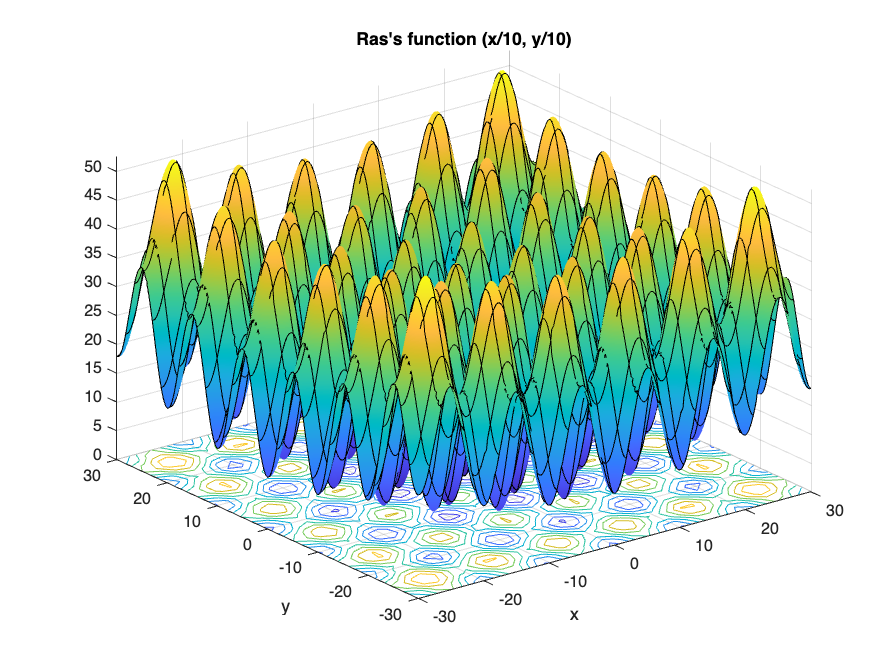

% rastrigin's function has many local minima and a global max:

ras = @(x,y) 20 + x.^2 + y.^2 - 10*(cos(2*pi*x) + cos(2*pi*y));


rf3 = @(x,y) ras(x/10, y/10);
fsurf(rf3,[-30 30],"ShowContours","on")
title("Ras's function (x/10, y/10)")
xlabel("x")
ylabel("y")

% Using fminunc solver:

x = optimvar("x");
y = optimvar("y");
prob = optimproblem("Objective", rf3(x,y));

x0.x = 20;
x0.y = 30;

[solf, fvalf eflagf, outputf] = solve(prob,x0)

Solving problem using fminunc.

Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


solf = struct with fields:
    x: 19.8991
    y: 29.8486


fvalf = 12.9344

eflagf =     OptimalSolution


outputf = struct with fields:
             iterations: 3
              funcCount: 5
               stepsize: 1.7773e-06
           lssteplength: 1
          firstorderopt: 2.0461e-09
              algorithm: 'quasi-newton'
                message: 'Local minimum found.↵↵Optimization completed because the size of the gradient is less than↵the value of the optimality tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The first-order optimality measure, 1.278784e-09, is less ↵than options.OptimalityTolerance = 1.000000e-06.'
    objectivederivative: "reverse-AD"
                 solver: 'fminunc'


Solves with only 5 function calls, exit flag indicates its a local minimum

% Patternsearch solver

x0.x = 20;
x0.y = 30;

[solp,fvalp, eflagp, outputp] = solve(prob, x0, "Solver","patternsearch")

Solving problem using patternsearch.
Optimization terminated: mesh size less than options.MeshTolerance.


solp = struct with fields:
    x: 19.8991
    y: -9.9496


fvalp = 4.9748

eflagp =     SolverConvergedSuccessfully


outputp = struct with fields:
         function: @(x)fun(x,extraParams)
      problemtype: 'unconstrained'
       pollmethod: 'gpspositivebasis2n'
    maxconstraint: []
     searchmethod: []
       iterations: 48
        funccount: 174
         meshsize: 9.5367e-07
         rngstate: [1×1 struct]
          message: 'Optimization terminated: mesh size less than options.MeshTolerance.'
           solver: 'patternsearch'


% works slightly better

% ga solver:

rng default % For reproducibility
x0.x = 10*randn(20) + 20;
x0.y = 10*randn(20) + 30; % Random start population near [20,30];
[solg,fvalg,eflagg,outputg] = solve(prob,"Solver","ga")

Solving problem using ga.
Optimization terminated: maximum number of generations exceeded.


solg = struct with fields:
    x: 0.0064
    y: 7.7057e-04


fvalg = 8.1608e-05

eflagg =     SolverLimitExceeded


outputg = struct with fields:
      problemtype: 'unconstrained'
         rngstate: [1×1 struct]
      generations: 200
        funccount: 9453
          message: 'Optimization terminated: maximum number of generations exceeded.'
    maxconstraint: []
       hybridflag: []
           solver: 'ga'


% very close to true solution

% particleswarm solver

rng default % For reproducibility
[solpso,fvalpso,eflagpso,outputpso] = solve(prob,"Solver","particleswarm")

Solving problem using particleswarm.
Optimization ended: relative change in the objective value 
over the last OPTIONS.MaxStallIterations iterations is less than OPTIONS.FunctionTolerance.


solpso = struct with fields:
    x: 7.1467e-07
    y: 1.4113e-06


fvalpso = 4.9631e-12

eflagpso =     SolverConvergedSuccessfully


outputpso = struct with fields:
      rngstate: [1×1 struct]
    iterations: 120
     funccount: 2420
       message: 'Optimization ended: relative change in the objective value ↵over the last OPTIONS.MaxStallIterations iterations is less than OPTIONS.FunctionTolerance.'
    hybridflag: []
        solver: 'particleswarm'


% simulannealbnd solver

rng default % For reproducibility
x0.x = 20;
x0.y = 30;
[solsim,fvalsim,eflagsim,outputsim] = solve(prob,x0,"Solver","simulannealbnd")

Solving problem using simulannealbnd.
Optimization terminated: change in best function value less than options.FunctionTolerance.


solsim = struct with fields:
    x: 0.0025
    y: 0.0018


fvalsim = 1.8311e-05

eflagsim =     SolverConvergedSuccessfully


outputsim = struct with fields:
     iterations: 1967
      funccount: 1986
        message: 'Optimization terminated: change in best function value less than options.FunctionTolerance.'
       rngstate: [1×1 struct]
    problemtype: 'unconstrained'
    temperature: [2×1 double]
      totaltime: 0.9555
         solver: 'simulannealbnd'




% surrogateopt solver

rng default % For reproducibility
x = optimvar("x","LowerBound",-70,"UpperBound",130);
y = optimvar("y","LowerBound",-70,"UpperBound",130);
prob = optimproblem("Objective",rf3(x,y));
options = optimoptions("surrogateopt","PlotFcn",[]);
[solsur,fvalsur,eflagsur,outputsur] = solve(prob,...
    "Solver","surrogateopt",...
    "Options",options)

Solving problem using surrogateopt.
surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.


solsur = struct with fields:
    x: -1.3383
    y: -0.3022


fvalsur = 3.5305

eflagsur =     SolverLimitExceeded


outputsur = struct with fields:
        elapsedtime: 6.9117
          funccount: 200
    constrviolation: 0
               ineq: [1×1 struct]
           rngstate: [1×1 struct]
            message: 'surrogateopt stopped because it exceeded the function evaluation limit set by ↵'options.MaxFunctionEvaluations'.'
             solver: 'surrogateopt'


## Summary of solvers:

sols = [solf.x solf.y;
    solp.x solp.y;
    solg.x solg.y;
    solpso.x solpso.y;
    solsim.x solsim.y;
    solsur.x solsur.y];
fvals = [fvalf;
    fvalp;
    fvalg;
    fvalpso;
    fvalsim;
    fvalsur];
fevals = [outputf.funcCount;
    outputp.funccount;
    outputg.funccount;
    outputpso.funccount;
    outputsim.funccount;
    outputsur.funccount];
stats = table(sols,fvals,fevals);
stats.Properties.RowNames = ["fminunc" "patternsearch" "ga" "particleswarm" "simulannealbnd" "surrogateopt"];
stats.Properties.VariableNames = ["Solution" "Objective" "# Fevals"];
disp(stats)

                              Solution            Objective     # Fevals
                      ________________________    __________    ________

    fminunc               19.899        29.849        12.934         5  
    patternsearch         19.899       -9.9496        4.9748       174  
    ga                 0.0063672    0.00077057    8.1608e-05      9453  
    particleswarm     7.1467e-07    1.4113e-06    4.9631e-12      2420  
    simulannealbnd      0.002453     0.0017923    1.8311e-05      1986  
    surrogateopt         -1.3383      -0.30217        3.5305       200  



These results are typical:

- `fminunc` quickly reaches the local solution within its starting basin, but does not explore outside this basin at all. Because the objective function has analytic derivatives, `fminunc` uses automatic differentiation and takes very few function evaluations to reach an accurate local minimum.

- `patternsearch` takes more function evaluations than `fminunc`, and searches through several basins, arriving at a better solution than `fminunc`.

- `ga` takes many more function evaluations than `patternsearch`. By chance it arrives at a better solution. In this case, `ga` finds a point near the global optimum. `ga` is stochastic, so its results change with every run. `ga` requires extra steps to have an initial population near [20,30].

- `particleswarm` takes fewer function evaluations than `ga`, but more than `patternsearch`. In this case, `particleswarm` finds a point with lower objective function value than `patternsearch` or `ga`. Because `particleswarm` is stochastic, its results change with every run. `particleswarm` requires extra steps to have an initial population near [20,30].

- `simulannealbnd` takes about the same number of function evaluations as `particleswarm`. In this case, `simulannealbnd` finds a good solution, but not as good as `particleswarm`. The solver is stochastic and can arrive at a suboptimal solution.

- `surrogateopt` stops when it reaches a function evaluation limit, which by default is 200 for a two-variable problem. `surrogateopt` requires finite bounds. `surrogateopt` attempts to find a global solution, and in this case succeeds. Each function evaluation in `surrogateopt` takes a longer time than in most other solvers, because `surrogateopt` performs many auxiliary computations as part of its algorithm.